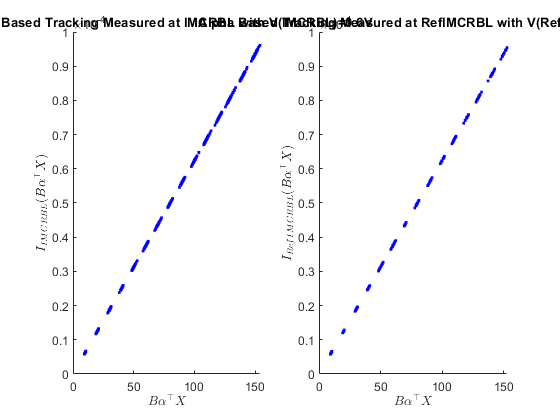

clear;clc;
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v3\MATLAB_CONTROL\Control_Codes\Testing\017_ReadStackAlphaMeasurement\Sno_2_Results\IMC_RBL_Synthetic.mat');
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v3\MATLAB_CONTROL\Control_Codes\Testing\017_ReadStackAlphaMeasurement\Sno_2_Results\RefIMC_RBL_Synthetic.mat');
load('dataCols.mat');
IMC_RBL_CurrSums=reshape(IMC_RBL_ReadStacks,72,size(dataCols,1));
RefIMC_RBL_CurrSums=reshape(RefIMC_RBL_ReadStacks,16,size(dataCols,1));
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v3\MATLAB_CONTROL\Control_Codes\Testing\017_ReadStackAlphaMeasurement\alphaStored\alphas.mat');
MACs_IMCRBL_Sums=dataCols(:,1:1024)*(alpha_DLStore);MACs_IMCRBL_Sums=MACs_IMCRBL_Sums';
MACs_RefIMCRBL_Sums=dataCols(:,1:1024)*(alpha_RLStore);MACs_RefIMCRBL_Sums=MACs_RefIMCRBL_Sums';
figure;
subplot(1,2,1);
scatter(MACs_IMCRBL_Sums(:),IMC_RBL_CurrSums(:),'.b');
title('Alpha Based Tracking Measured at IMCRBL with V(IMCRBL)=0.6V');
xlabel('$B\alpha^\top X$', 'Interpreter',"latex");
ylabel('$I_{IMCRBL}(B\alpha^\top X)$', 'Interpreter',"latex");
subplot(1,2,2);
scatter(MACs_RefIMCRBL_Sums(:),RefIMC_RBL_CurrSums(:),'.b');
title('Alpha Based Tracking Measured at RefIMCRBL with V(RefRBL)=0.6V');
xlabel('$B\alpha^\top X$', 'Interpreter',"latex");
ylabel('$I_{RefIMCRBL}(B\alpha^\top X)$', 'Interpreter',"latex");

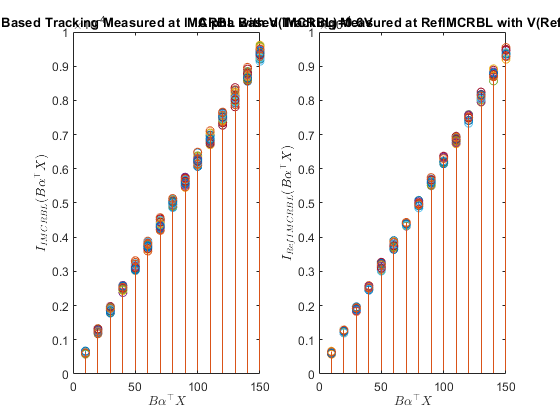


figure;
subplot(1,2,1);
stem([10:10:150],IMC_RBL_CurrSums');
title('Alpha Based Tracking Measured at IMCRBL with V(IMCRBL)=0.6V');
xlabel('$B\alpha^\top X$', 'Interpreter',"latex");
ylabel('$I_{IMCRBL}(B\alpha^\top X)$', 'Interpreter',"latex");
subplot(1,2,2);
stem([10:10:150],RefIMC_RBL_CurrSums');
title('Alpha Based Tracking Measured at RefIMCRBL with V(RefRBL)=0.6V');
xlabel('$B\alpha^\top X$', 'Interpreter',"latex");
ylabel('$I_{RefIMCRBL}(B\alpha^\top X)$', 'Interpreter',"latex");